# UAV Package Delivery

This example shows through incremental design iterations, learn how to implement a small multicopter simulation to takeoff, fly, and land at a different location in a city environment. 

## Open the Project

To get started, open the example live script and access the supporting files by either clicking **Open Live Script** in the documentation or using the `openExample` function.

Then, open the Simulink™ project file. 

prj = openProject('uavPackageDelivery.prj');

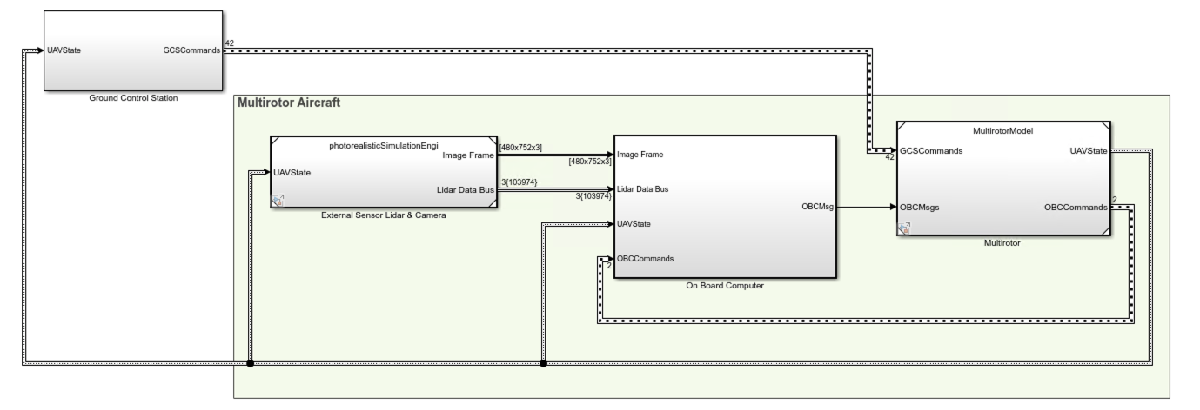

## Model Architecture and Conventions

The top model consists of the following subsystems and model references:

- **Ground Control Station:**  Used to control and monitor the aircraft while in-flight.

- **External Sensors - Lidar & Camera:** Used to connect to previously-designed scenario or a Photorealistic simulation environment. These produce Lidar readings from the environment as the aircraft flies through it.

- **On Board Computer:** Used to implement algorithms meant to run in an on-board computer independent from the Autopilot.

- **Multirotor: **Includes a low-fidelity and mid-fidelity multicopter mode, a flight controller including its guidance logic.   

The model's design data is contained in a Simulink™ data dictionary in the **data** folder (`uavPackageDeliveryDataDict.sldd`). Additionally, the model uses [**Variants**](docid:simulink_ug#bvhtavr) to manage different configurations of the model. Variables placed in the base workspace configure these variants without the need to modify the data dictionary.

## Following Example Steps

Use the **Project Shortcuts** to step through the example. Each shortcut sets up the required variables for the project.

## 1. Getting Started

Click the **Getting Started** project shortcut, which sets up the model for a four-waypoint mission using a low-fidelity multirotor plant model. **Run** the `uavPackageDelivery` model, which shows the multirotor takeoff, fly, and land in a 3-D plot.  

 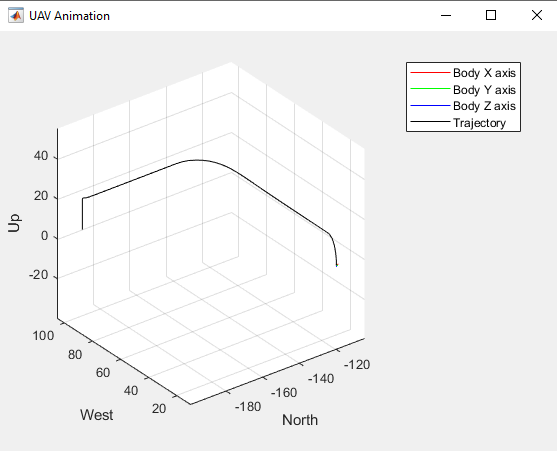

The model uses **UAV Path Manager** block to determine which is the active waypoint throughout the flight. The active waypoint is passed into the **Guidance Mode Selector** Stateflow™ chart to generate the necessary inner loop control commands.

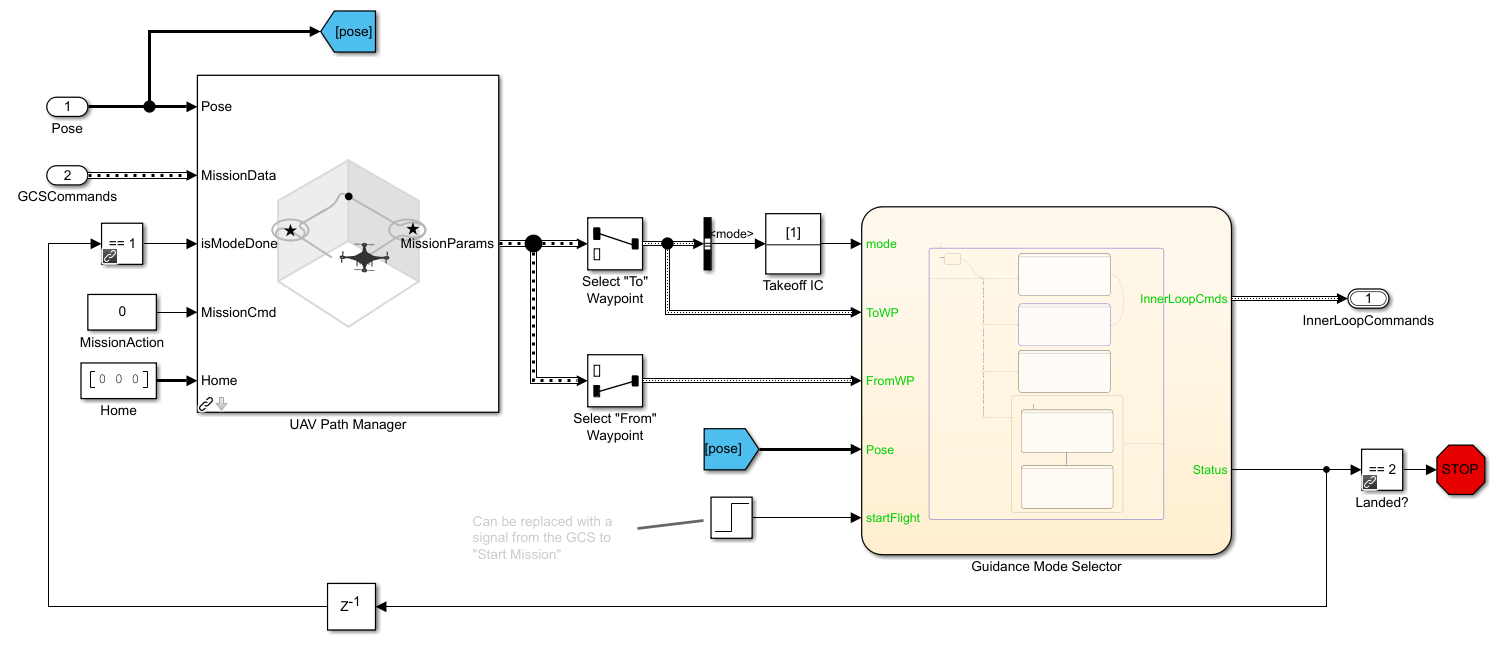

## **2. Connecting to a GCS**

Once you are able to fly a basic mission, you are ready to integrate your simulation with a Ground Station Software so you can better control the aircraft's mission. For this, you need to download and install [QGroundControl](http://qgroundcontrol.com/) Ground Control Station software. 

The model uses the UAV Toolbox™ [MAVLink Support](docid:uav_ref#mw_a42d7e4d-a619-464d-9689-b0efba50ee94) to establish a connection between Simulink and QGroundControl. The connection is implemented as a MATLAB® System Block located in `uavPackageDelivery/Ground Control Station/Get Flight Mission/QGC/MAVLink Interface`.

To test the connectivity between Simulink and QGroundControl follow these steps:

- Click the **Connecting to a GCS** project shortcut.

- Launch QGroundControl.

- In QGroundControl, load the mission plan named `shortMission.plan` located in `/utilities/qgc`. 

- **Run** the simulation.

- When QGroundControl indicates that it is connected to the system, upload the mission.

Once the aircraft takes off, you should see the UAV fly its mission as sent by QGC as shown below. 

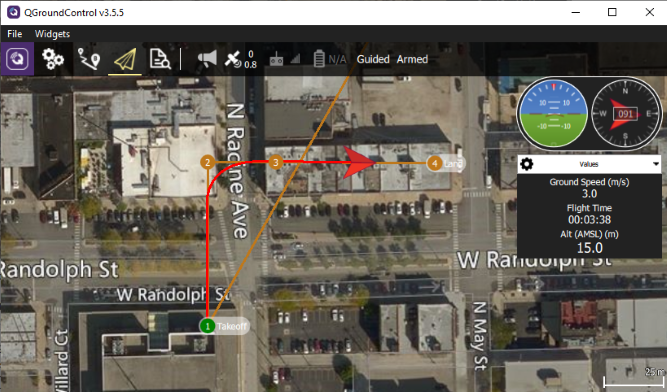

You can modify the mission by adding waypoints or moving those that are already in the mission. Upload the mission and the aircraft should respond to these changes.

## 3. Setting a Cuboid Scenario

Now that aircraft's model can be flow from a ground control station, consider the environment the aircraft flies in. For this example, a few city blocks are modeled in a cuboid scenario using the [`uavScenario`](docid:uav_ref#mw_a038cc32-74b4-4d65-a325-1a8dae51a1c7) object. The scenario is based on the city block shown in the left figure below.

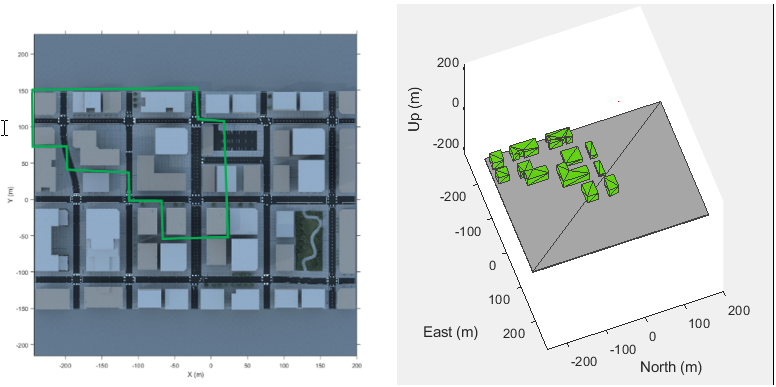

To safely fly the aircraft in this type of scenario, you need a sensor that provides information about the environment such as a lidar sensor to the model. This example uses a `uavLidarPointCloudGenerator` object added to the UAV scenario with a `uavSensor` object. The lidar sensor model generates readings based on the pose of the sensor and the obstacles in the environment.

Click the **Setting a Cuboid Scenario** shortcut and **Run** the model. As the model runs, a lidar point cloud image is displayed as the aircraft flies through the cuboid environment:

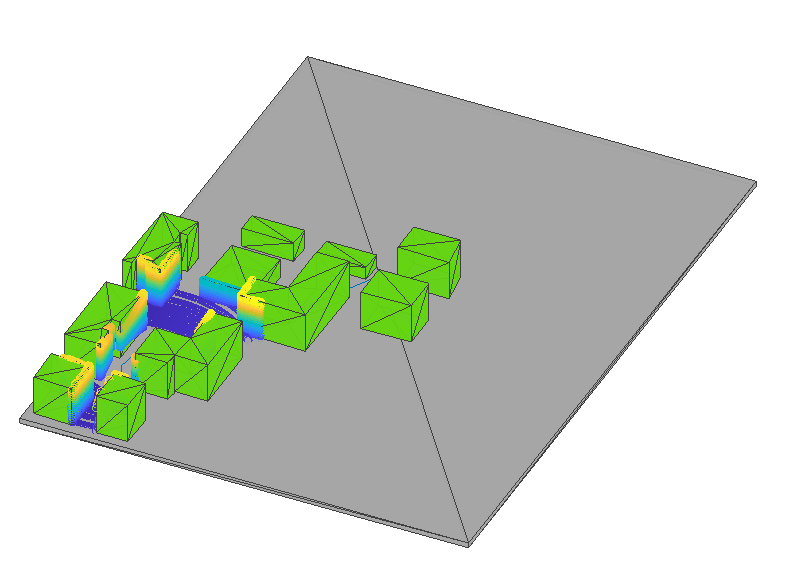

## 4. Obstacle Avoidance

To avoid obstacles in the environment, the model must use the available sensor data as the UAV flies the mission in the environment. To modify the model configuration, click the **Obstacle Avoidance** or **3D Obstacle Avoidance **shortcut. A scope appears that shows the closest point to a building in the cuboid environment. **Obstacle Avoidance **shortcut configures the model to use planar lidar information and [**Vector Field Histogram block**](docid:nav_ref#bvam7nc) to avoid obstacles by changing the direction of the UAV in its current x-y plane. **3D Obstacle Avoidance** shortcut configures the model to use 3D lidar points and [**Obstacle Avoidance block**](docid:uav_ref#mw_5efb91c2-4a01-4ae1-9e05-287bdcf49a89) to avoid obstacles by changing the direction of the UAV in 3D space.

**Run** the model. In **Obstacle Avoidance** mode, as the model runs, the aircraft attempts to fly in a straight path between buildings to a drop site but deviates to avoid obstacles along the way. Observe the change in distance to obstacles over time and observe a similar behavior in **3D Obstacle Avoidance** mode, with the UAV now also able to adjust altitude to fly over obstacles.

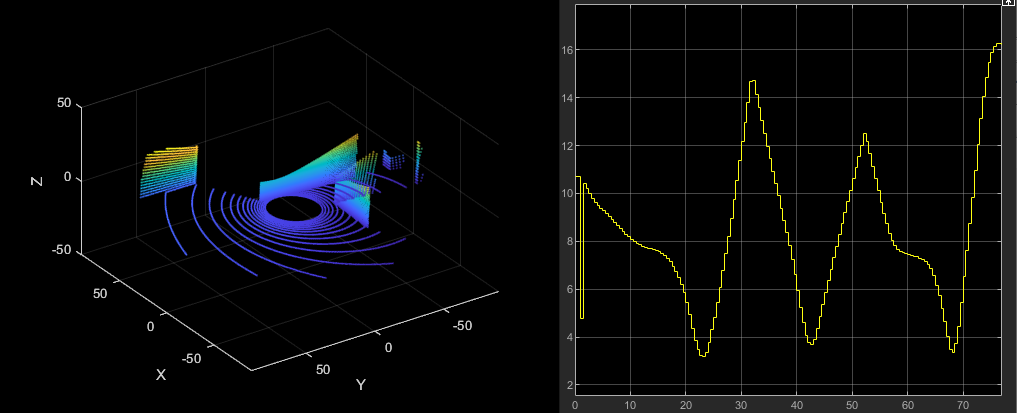

## 5. Photorealistic Simulation

Up to this point, the environment has been a simple cuboid scenario. To increase the fidelity of the environment, click the **Photorealistic Simulation** shortcut, which places the aircraft in a more realistic world to fly through. The `PhotorealisticQuadrotor` variant located at `uavPackageDelivery/photorealisticSimulationEngi/SimulationEnvironmentVariant` becomes active. This variant contains the necessary blocks to configure the simulation environment and the sensors mounted on the aircraft:

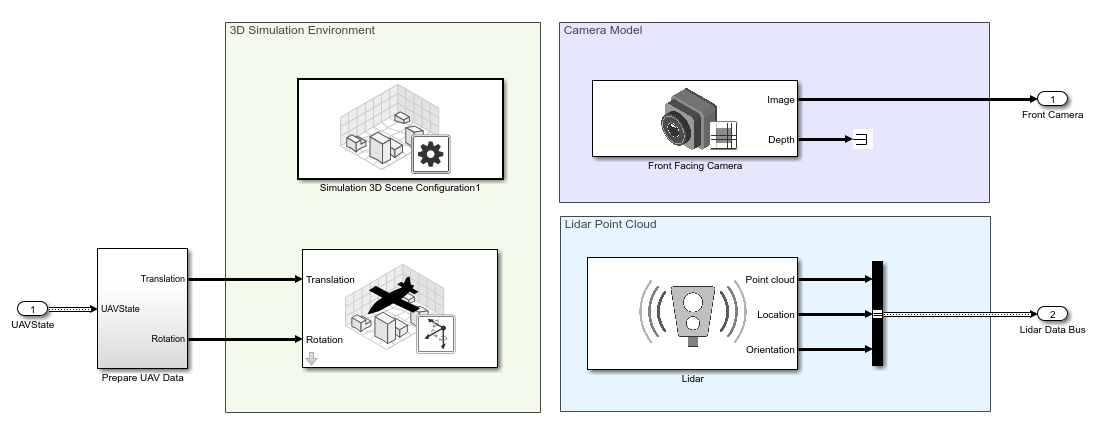

**Run** the model. The aircraft is set up to fly the same mission from steps 1 and 2.  Notice as the aircraft flies the mission the lidar point clouds update and an image from the front-facing camera is shown.

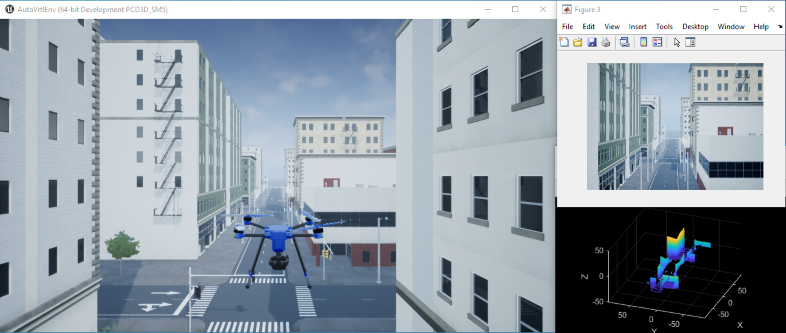

## 6. Fly Full Mission in a Photorealistic Simulation Environment

Next, click the **Fly full mission** shortcut, which sets up the connectivity to QGroundControl from step 2 for uploading the mission inside the photorealistic environment. Follow these steps to run the simulation:

- Launch QGroundControl. 

- In QGroundControl, load the mission plan named `shortMission.plan` located in `/utilities/qgc`. 

- **Run** the Simulation.

- When QGroundControl indicates that it is connected to a system, upload the mission.

As the aircraft starts to fly, you can modify the mission in QGroundControl by adding waypoints or moving those that are already in the mission. Upload the mission and the aircraft should respond to these changes. Throughout the flight you'll see the aircraft flying in the scenario.

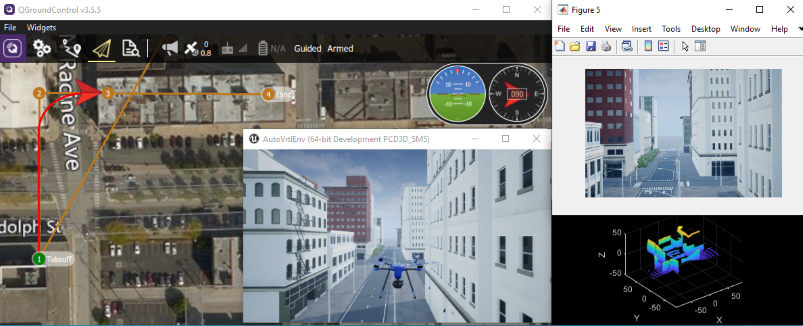

## 7. Flying Obstacle Avoidance in a Photorealistic Simulation Environment

Next, the goal is to fly a mission by specifying a takeoff and landing point in QGroundControl and using the obstacle avoidance to navigate around the obstacles along the path. Click the **Fly full Obstacle Avoidance **or** Fly full 3D Obstacle Avoidance** shortcut and follow these steps to run the simulation:

- Launch QGroundControl. 

- In QGroundControl, load the mission plan named `oaMission.plan` located in `/utilities/qgc`. 

- **Run** the Simulation.

- When QGroundControl indicates that it is connected to a system, upload the mission.

Throughout the flight, watch the aircraft try to follow the commanded path in QGroundControl, while at the same time attempting to avoid colliding with the buildings in the environment. If **Fly full 3D Obstacle Avoidance **is used, the UAV flies over the lower buildings rather than around it.

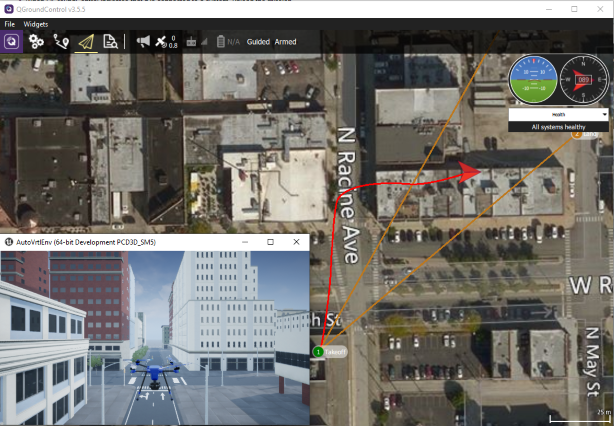

At some point during the flight, you will see the UAV fly around building corners.

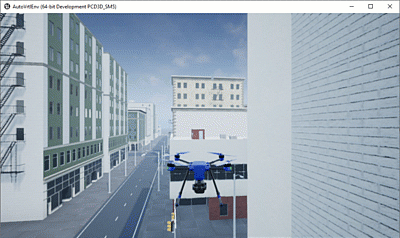

## 8. Adding a 6DOF Plant Model for Higher-Fidelity Simulation 

As a final step, click the **Adding a High Fidelity Plant** shortcut, which activates the high-fidelity variant of the UAV model located at `uavPackageDelivery/MultirotorModel/Inner Loop and Plant Model/High-FidelityModel`. This variant contains an inner-loop controller and a high-fidelity plant model.

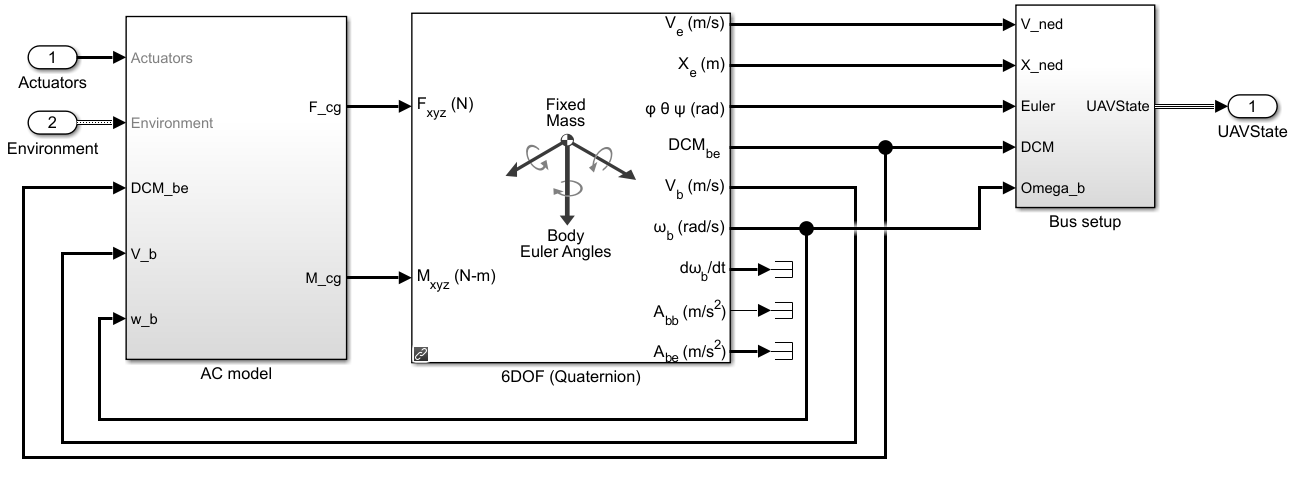

**Run** the model. There are minor changes in behavior due to the high-fidelity model, but the UAV flies the same mission.

When you are done exploring the models, close the project file. 

close(prj);

*Copyright 2020-2021 The MathWorks, Inc.*